clc; clear all;
rng(43);
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;

taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);

taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))

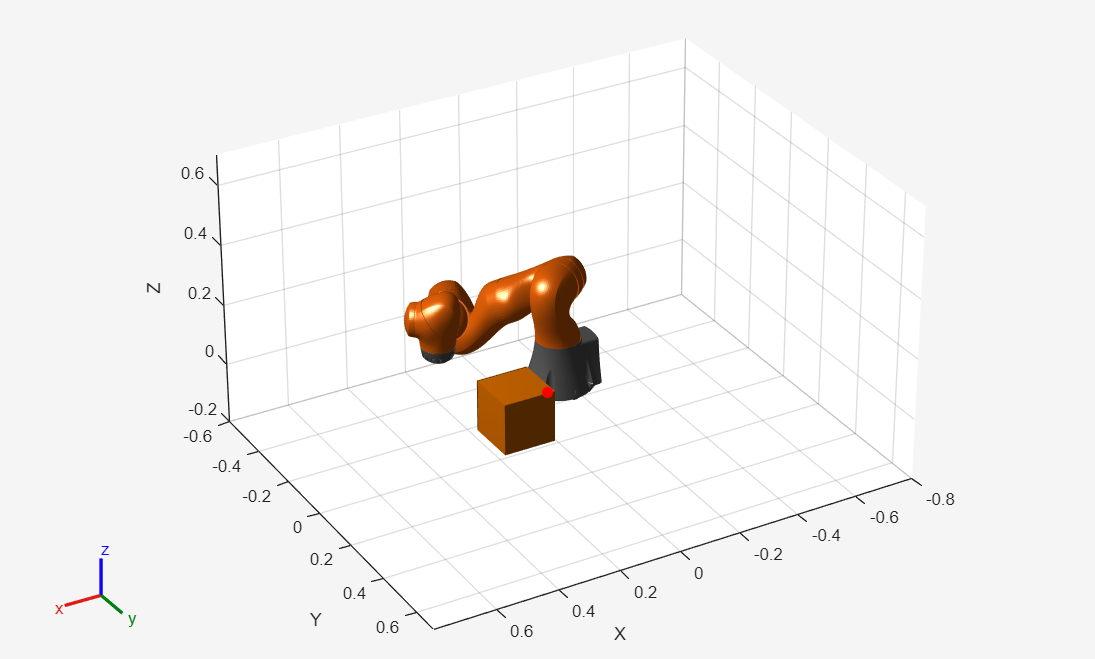

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.959668 seconds.


Qtheta = 1.9902e+03

RAR = 113.0758

Previous Qθ = 2013.078630 | New Qθ = 1990.155632 | ΔQ = 22.922998
Elapsed time is 1.809570 seconds.


Qtheta = 1.9484e+03

RAR = 113.0908

Previous Qθ = 1990.155632 | New Qθ = 1948.414808 | ΔQ = 41.740824
Elapsed time is 1.765879 seconds.


Qtheta = 1.8499e+03

RAR = 113.0423

Previous Qθ = 1948.414808 | New Qθ = 1849.875469 | ΔQ = 98.539339
Elapsed time is 1.670278 seconds.


Qtheta = 1.8021e+03

RAR = 113.0980

Previous Qθ = 1849.875469 | New Qθ = 1802.096943 | ΔQ = 47.778526
Elapsed time is 1.788911 seconds.


Qtheta = 1.7495e+03

RAR = 113.0888

Previous Qθ = 1802.096943 | New Qθ = 1749.512525 | ΔQ = 52.584418
Elapsed time is 1.630972 seconds.


Qtheta = 1.6860e+03

RAR = 113.1088

Previous Qθ = 1749.512525 | New Qθ = 1686.006223 | ΔQ = 63.506302
Elapsed time is 1.631653 seconds.


Qtheta = 1.6513e+03

RAR = 113.0957

Previous Qθ = 1686.006223 | New Qθ = 1651.251210 | ΔQ = 34.755013
Elapsed time is 1.631581 seconds.


Qtheta = 1.6164e+03

RAR = 113.1227

Previous Qθ = 1651.251210 | New Qθ = 1616.360593 | ΔQ = 34.890617
Elapsed time is 1.620022 seconds.


Qtheta = 1.5675e+03

RAR = 113.1250

Previous Qθ = 1616.360593 | New Qθ = 1567.454627 | ΔQ = 48.905966
Elapsed time is 1.657539 seconds.


Qtheta = 1.5578e+03

RAR = 113.1322

Previous Qθ = 1567.454627 | New Qθ = 1557.802480 | ΔQ = 9.652146
Elapsed time is 1.683006 seconds.


Qtheta = 1.5278e+03

RAR = 113.1109

Previous Qθ = 1557.802480 | New Qθ = 1527.779716 | ΔQ = 30.022764
Elapsed time is 1.639143 seconds.


Qtheta = 1.5186e+03

RAR = 113.1423

Previous Qθ = 1527.779716 | New Qθ = 1518.612884 | ΔQ = 9.166833
Elapsed time is 1.595431 seconds.


Qtheta = 1.4961e+03

RAR = 113.1530

Previous Qθ = 1518.612884 | New Qθ = 1496.147792 | ΔQ = 22.465091
Elapsed time is 1.680714 seconds.


Qtheta = 1.4671e+03

RAR = 113.1650

Previous Qθ = 1496.147792 | New Qθ = 1467.134003 | ΔQ = 29.013789
Elapsed time is 1.599254 seconds.


Qtheta = 1.4635e+03

RAR = 113.1390

Previous Qθ = 1467.134003 | New Qθ = 1463.458001 | ΔQ = 3.676002
Elapsed time is 1.619544 seconds.


Qtheta = 1.4374e+03

RAR = 113.1485

Previous Qθ = 1463.458001 | New Qθ = 1437.439017 | ΔQ = 26.018984
Elapsed time is 1.658578 seconds.


Qtheta = 1.4152e+03

RAR = 113.1723

Previous Qθ = 1437.439017 | New Qθ = 1415.243583 | ΔQ = 22.195434
Elapsed time is 1.704910 seconds.


Qtheta = 1.4008e+03

RAR = 113.1675

Previous Qθ = 1415.243583 | New Qθ = 1400.841778 | ΔQ = 14.401806
Elapsed time is 1.620721 seconds.


Qtheta = 1.3823e+03

RAR = 113.1957

Previous Qθ = 1400.841778 | New Qθ = 1382.349318 | ΔQ = 18.492460
Elapsed time is 1.669170 seconds.


Qtheta = 1.3674e+03

RAR = 113.1984

Previous Qθ = 1382.349318 | New Qθ = 1367.427932 | ΔQ = 14.921386
Elapsed time is 1.625237 seconds.


Qtheta = 1.3440e+03

RAR = 113.2246

Previous Qθ = 1367.427932 | New Qθ = 1343.959875 | ΔQ = 23.468057
Elapsed time is 1.614423 seconds.


Qtheta = 1.3331e+03

RAR = 113.2052

Previous Qθ = 1343.959875 | New Qθ = 1333.122362 | ΔQ = 10.837513
Elapsed time is 1.605850 seconds.


Qtheta = 1.3034e+03

RAR = 113.1960

Previous Qθ = 1333.122362 | New Qθ = 1303.444025 | ΔQ = 29.678337
Elapsed time is 1.620912 seconds.


Qtheta = 1.2863e+03

RAR = 113.1977

Previous Qθ = 1303.444025 | New Qθ = 1286.343021 | ΔQ = 17.101004
Elapsed time is 1.617968 seconds.


Qtheta = 1.2702e+03

RAR = 113.2310

Previous Qθ = 1286.343021 | New Qθ = 1270.224246 | ΔQ = 16.118775
Elapsed time is 1.633983 seconds.


Qtheta = 1.2646e+03

RAR = 113.2248

Previous Qθ = 1270.224246 | New Qθ = 1264.641353 | ΔQ = 5.582893
Elapsed time is 1.636578 seconds.


Qtheta = 1.2453e+03

RAR = 113.2762

Previous Qθ = 1264.641353 | New Qθ = 1245.292222 | ΔQ = 19.349131
Elapsed time is 1.611766 seconds.


Qtheta = 1.2254e+03

RAR = 113.2597

Previous Qθ = 1245.292222 | New Qθ = 1225.369139 | ΔQ = 19.923082
Elapsed time is 1.716354 seconds.


Qtheta = 1.2167e+03

RAR = 113.2633

Previous Qθ = 1225.369139 | New Qθ = 1216.708899 | ΔQ = 8.660240
Elapsed time is 1.660276 seconds.


Qtheta = 1.1954e+03

RAR = 113.2728

Previous Qθ = 1216.708899 | New Qθ = 1195.362222 | ΔQ = 21.346677
Elapsed time is 1.679258 seconds.


Qtheta = 1.1872e+03

RAR = 113.2821

Previous Qθ = 1195.362222 | New Qθ = 1187.157911 | ΔQ = 8.204311
Elapsed time is 1.685844 seconds.


Qtheta = 1.1753e+03

RAR = 113.2910

Previous Qθ = 1187.157911 | New Qθ = 1175.321024 | ΔQ = 11.836888
Elapsed time is 1.687949 seconds.


Qtheta = 1.1560e+03

RAR = 113.2714

Previous Qθ = 1175.321024 | New Qθ = 1155.952418 | ΔQ = 19.368605
Elapsed time is 1.615084 seconds.


Qtheta = 1.1471e+03

RAR = 113.2303

Previous Qθ = 1155.952418 | New Qθ = 1147.071946 | ΔQ = 8.880472
Elapsed time is 1.625682 seconds.


Qtheta = 1.1438e+03

RAR = 113.2218

Previous Qθ = 1147.071946 | New Qθ = 1143.797622 | ΔQ = 3.274324
Elapsed time is 1.615777 seconds.


Qtheta = 1.1388e+03

RAR = 113.2490

Previous Qθ = 1143.797622 | New Qθ = 1138.844810 | ΔQ = 4.952812
Elapsed time is 1.615554 seconds.


Qtheta = 1.1357e+03

RAR = 113.2685

Previous Qθ = 1138.844810 | New Qθ = 1135.695299 | ΔQ = 3.149511
Elapsed time is 1.612164 seconds.


Qtheta = 1.1334e+03

RAR = 113.2618

Previous Qθ = 1135.695299 | New Qθ = 1133.364374 | ΔQ = 2.330926
Elapsed time is 1.625771 seconds.


Qtheta = 1.1271e+03

RAR = 113.2452

Previous Qθ = 1133.364374 | New Qθ = 1127.084634 | ΔQ = 6.279740
Elapsed time is 1.620225 seconds.


Qtheta = 1.1191e+03

RAR = 113.2521

Previous Qθ = 1127.084634 | New Qθ = 1119.074447 | ΔQ = 8.010186
Elapsed time is 1.613442 seconds.


Qtheta = 1.1161e+03

RAR = 113.2160

Previous Qθ = 1119.074447 | New Qθ = 1116.069318 | ΔQ = 3.005130
Elapsed time is 1.614216 seconds.


Qtheta = 1.1167e+03

RAR = 113.1859

Previous Qθ = 1116.069318 | New Qθ = 1116.701421 | ΔQ = 0.632103
Elapsed time is 1.613662 seconds.


Qtheta = 1.1094e+03

RAR = 113.1925

Previous Qθ = 1116.701421 | New Qθ = 1109.379453 | ΔQ = 7.321968
Elapsed time is 1.644181 seconds.


Qtheta = 1.1093e+03

RAR = 113.2058

Previous Qθ = 1109.379453 | New Qθ = 1109.345543 | ΔQ = 0.033909
STOMP Finished.


isTrajectoryInCollision = logical
   0


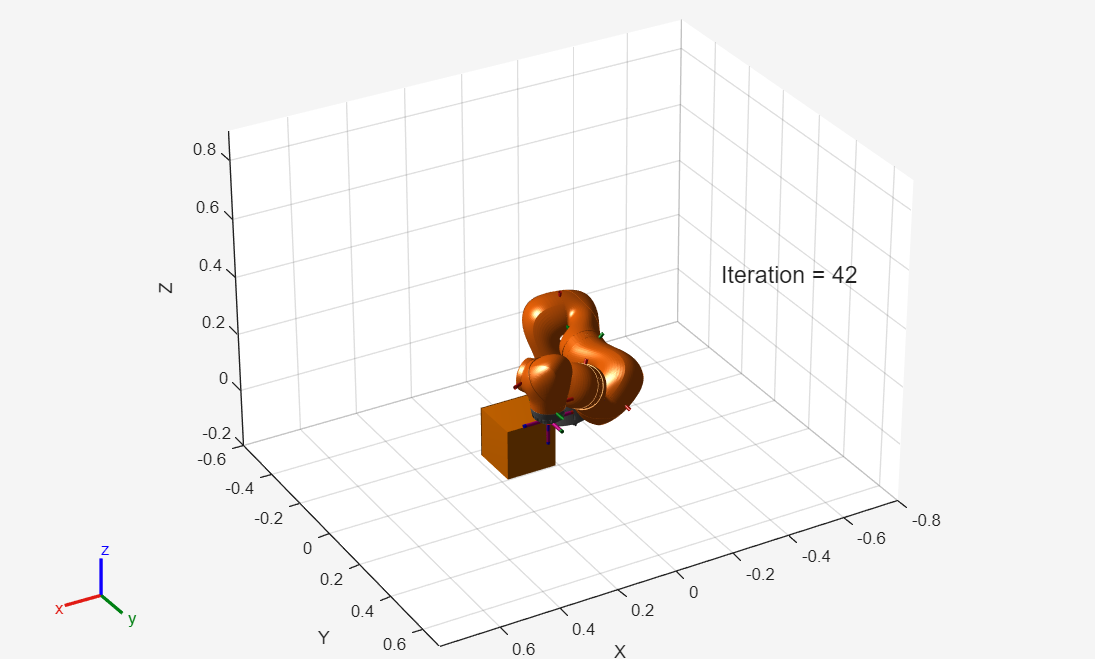

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;